clear

syms ssymb K

G(ssymb,K) = K*(ssymb-1)/(ssymb*(ssymb+10))

$$G(ssymb, K) = \frac{K\,\left(\mathrm{ssymb}-1\right)}{\mathrm{ssymb}\,\left(\mathrm{ssymb}+10\right)}$$

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.




Ks=-1

Ks = -1


Gs = Ks*(s-1)/(s*(s+10))

Gs =
 
    -s + 1
  ----------
  s^2 + 10 s
 
Continuous-time transfer function.



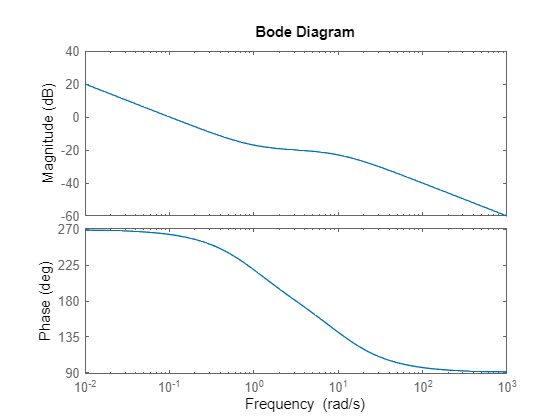


figure
bode(Gs)

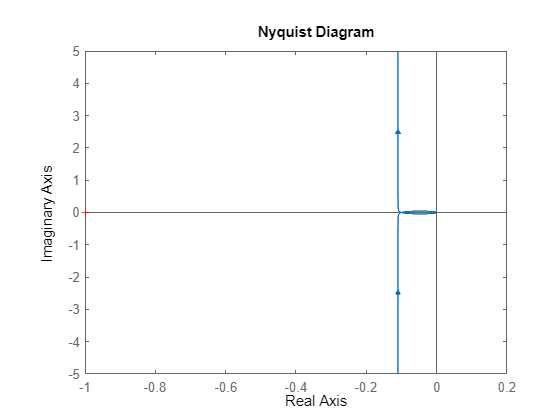

figure
nyquist(Gs)

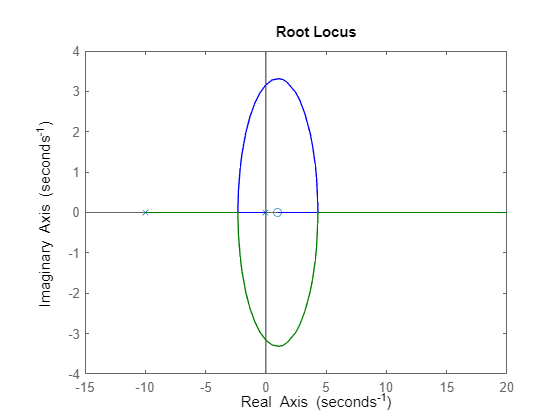

figure
rlocus(Gs)

syms w x

G(ssymb,K) =K*(ssymb-1)/(ssymb*(ssymb+10));
G(ssymb,-1)

$$ans = -\frac{\mathrm{ssymb}-1}{\mathrm{ssymb}\,\left(\mathrm{ssymb}+10\right)}$$

expand(G)

$$ans(ssymb, K) = \frac{K\,\mathrm{ssymb}}{{\mathrm{ssymb}}^{2}+10\,\mathrm{ssymb}}-\frac{K}{{\mathrm{ssymb}}^{2}+10\,\mathrm{ssymb}}$$


G(1j*w,K);
W1 = double(solve(imag(G(1j*w,K))==0,w,"Real",true))

W1 =     3.1623
   -3.1623


K_theo=double(solve(real(G(1j*W1(1),K))==-1,K))

K_theo = -10


double(solve(x^2+9*x+1))

ans =    -8.8875
   -0.1125


solve1 = solve(x^2+9*x+1)

$$solve1 = \left(\begin{array}{c} -\frac{\sqrt{77}}{2}-\frac{9}{2}\\ \frac{\sqrt{77}}{2}-\frac{9}{2} \end{array}\right)$$


T(ssymb)=G(ssymb,-1)/(1+G(ssymb,-1))

$$T(ssymb) = \frac{\mathrm{ssymb}-1}{\mathrm{ssymb}\,\left(\frac{\mathrm{ssymb}-1}{\mathrm{ssymb}\,\left(\mathrm{ssymb}+10\right)}-1\right)\,\left(\mathrm{ssymb}+10\right)}$$

expand(T(ssymb))

$$ans = \begin{array}{l} \frac{1}{\sigma_{1}}-\frac{\mathrm{ssymb}}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=10\,\mathrm{ssymb}+\frac{10\,\mathrm{ssymb}}{{\mathrm{ssymb}}^{2}+10\,\mathrm{ssymb}}-\frac{9\,{\mathrm{ssymb}}^{2}}{{\mathrm{ssymb}}^{2}+10\,\mathrm{ssymb}}-\frac{{\mathrm{ssymb}}^{3}}{{\mathrm{ssymb}}^{2}+10\,\mathrm{ssymb}}+{\mathrm{ssymb}}^{2} \end{array}$$

S1(ssymb) = T(ssymb)*(ssymb-solve1(1))

$$S1(ssymb) = \frac{\left(\mathrm{ssymb}-1\right)\,\left(\mathrm{ssymb}+\frac{\sqrt{77}}{2}+\frac{9}{2}\right)}{\mathrm{ssymb}\,\left(\frac{\mathrm{ssymb}-1}{\mathrm{ssymb}\,\left(\mathrm{ssymb}+10\right)}-1\right)\,\left(\mathrm{ssymb}+10\right)}$$

K1 = S1(solve1(1))

$$K1 = 0$$


[r,p,k] = residue([-1 1],[1 9 1])

r =    -1.1268
    0.1268


p =    -8.8875
   -0.1125



k =

     []



syms x1 x2 r ssymb
X=[x1; x2]

$$X = \left(\begin{array}{c} x_{1}\\ x_{2} \end{array}\right)$$


A=[0 -12; 1 -8]

A =      0   -12
     1    -8


B=[0;1]

B =      0
     1


C=[5 0]

C =      5     0


D=0

D = 0


X = A*X +B*r

$$X = \left(\begin{array}{c} -12\,x_{2}\\ r+x_{1}-8\,x_{2} \end{array}\right)$$


s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



z = tf('z')

z =
 
  z
 
Sample time: unspecified
Discrete-time transfer function.




G_ss_sym = C*inv(ssymb*eye(2)-A)*B

$$G\_ss\_sym = -\frac{60}{{\mathrm{ssymb}}^{2}+8\,\mathrm{ssymb}+12}$$

Gt_sym = ilaplace(G_ss_sym)

$$Gt\_sym = 15\,{\mathrm{e}}^{-6\,t}-15\,{\mathrm{e}}^{-2\,t}$$


G_ss = C*inv(s*eye(2)-A)*B

G_ss =
 
       -60
  --------------
  s^2 + 8 s + 12
 
Continuous-time transfer function.





G_sys = ss(A,B,C,D)

G_sys =
 
  A = 
        x1   x2
   x1    0  -12
   x2    1   -8
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   5   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



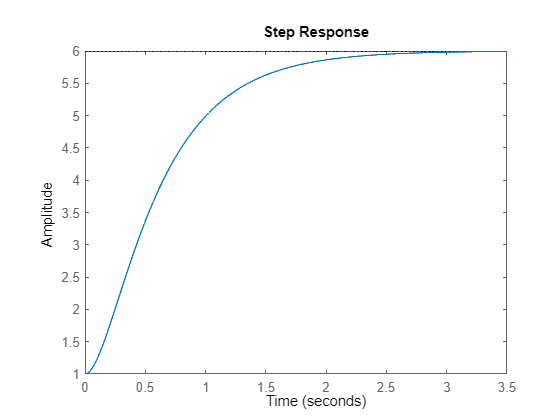


step(1-G_sys)

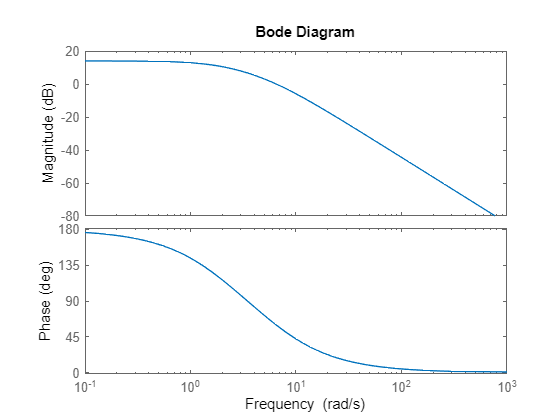

bode(G_sys)

syms T k
% Ad(T) = exp(A*T)
% Ad(0.1)
% double(Ad(0.1))
% 
% Bd(T) = inv(A)*(exp(A*T)-eye(2))*B
% Bd(0.1)
% double(Bd(0.1))

Ad(T) = [1 (1-exp(-T)); 0 exp(-T)]

$$Ad(T) = \left(\begin{array}{cc} 1 & 1-{\mathrm{e}}^{-T}\\ 0 & {\mathrm{e}}^{-T} \end{array}\right)$$

Bd(T) = [T-1+exp(-T); 1-exp(-T)]

$$Bd(T) = \left(\begin{array}{c} T+{\mathrm{e}}^{-T}-1\\ 1-{\mathrm{e}}^{-T} \end{array}\right)$$


Te=0.1

Te = 0.1000


Gd_sys = ss(double(Ad(Te)),double(Bd(Te)),C,0,Te)

Gd_sys =
 
  A = 
            x1       x2
   x1        1  0.09516
   x2        0   0.9048
 
  B = 
             u1
   x1  0.004837
   x2   0.09516
 
  C = 
       x1  x2
   y1   5   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



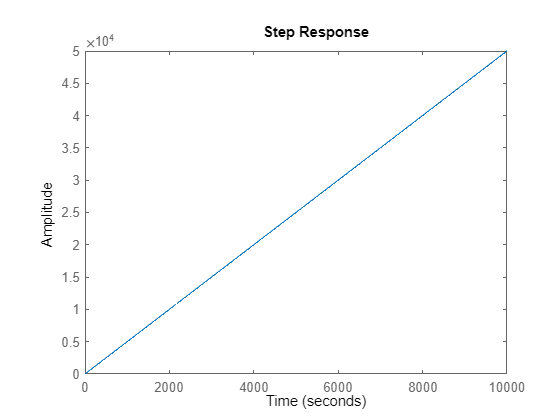


step(Gd_sys)


%x1(k) = x1(k-1) + (1-exp(-0.1))*x2(k) +(0.1 -1 + exp(-0.1))* r(k) 

Error using sym/subsindex
Invalid indexing or function definition. Indexing must follow MATLAB indexing. Function arguments must be symbolic variables, and function body must be sym expression.

Error in indexing (line 1075)
            R_tilde = builtin('subsref',L_tilde,Idx);

Related documentation

%fplot(x1(k),k)

Gz_ss_sym =(1-z^-1)*(c2d(G_ss/s,0.1))

Gz_ss_sym =
 
  -0.008235 z^3 - 0.0189 z^2 + 0.02161 z + 0.005522
  -------------------------------------------------
       z^4 - 2.368 z^3 + 1.817 z^2 - 0.4493 z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



Gz_ss_sym2 = c2d(G_ss,0.1,'zoh')

Gz_ss_sym2 =
 
    -0.2315 z - 0.1774
  ----------------------
  z^2 - 1.368 z + 0.4493
 
Sample time: 0.1 seconds
Discrete-time transfer function.

